clear all;
close all;

path_opt_table= readtable('traj_opt.csv');

s_opt_table= readtable('length_opt.csv');


bound_outer_table=readtable('rrc_outer.csv');

bound_inner_table=readtable('rrc_inner.csv');


ctrl_inputs_table= readtable('ctrl_inputs.csv');

xy_ref= [path_opt_table.x_Traj_x, path_opt_table.traj_y];
s_ref= s_opt_table.x_S_opt;
steer_ref= ctrl_inputs_table.x_Delta;

state_init= [xy_ref(1, 1), xy_ref(1,2) , 0, 0.0];
u_steer= deg2rad([-15:0.5:15]);
dt= 0.001/10;
s_predict=2.5; 
s_run= length(s_opt_table.x_S_opt);
dsteer= dt*deg2rad(15/1);

u_hist= [];
states_hist=[];
num_iter_hist=[];
v_last= 0;
steer_last= 0;

figure();

for i= 2:s_run
    ds= s_ref(i);
    state0= state_init;
    
    ref_devi= (xy_ref(i,2)- xy_ref(i-1,2))/(xy_ref(i,1)- xy_ref(i-1,1));
    dist_err_list=[];
    cord_err_list=[];
    devi_err_list=[];
    
    % generate path for each steer angle
    for j= 1:length(u_steer)
        
        [states_predict, u_predict, iter_predict]= LatticePathCreate(state_init, dt, u_steer(j), dsteer, v_last, steer_last, s_predict);
        states_predict= [state_init; states_predict];
        
        path_devi= (states_predict(end, 2)- state0(2))/((states_predict(end,1)- state0(1)));
        devi_err= abs(path_devi- ref_devi);
        devi_err_list= [devi_err_list; devi_err];
        

%         dist_err= (states_predict(:,1)- xy_ref(i, 1)).^2+ (states_predict(:,2)- xy_ref(i, 2)).^2;
%         dist_err_sum= sum(dist_err);
%         dist_err_list= [dist_err_list; dist_err_sum];
        
        
%         plot(states_predict(:,1), states_predict(:,2), "Color", "blue");
%         set(gca,'LooseInset',get(gca,'TightInset'))
%         % set(gca,'position',[0 0 1 1]);
%         hold on;
    end
    
    steer_id= find(devi_err_list== min(devi_err_list));
    %steer_id= find(dist_err_list== min(dist_err_list));
    
    [states_execute, u_execute, num_iter, steer_vector]= LatticePathCreate(state0, dt, u_steer(steer_id), dsteer, v_last, steer_last, ds);
    
%     plot(states_execute(:,1), states_execute(:,2), "Color", 'red',"LineWidth", 2.0);
%     hold on
%     plot(xy_ref(1:s_run, 1), xy_ref(1:s_run, 2), 'linewidth', 2.0, "Color", 'green', "LineStyle","--");
%     hold on
%     plot(states_execute(end,1), states_execute(end,2), "Color", 'black','Marker',"o");
%     xlabel("x(m)")
%     ylabel("y(m)")
    

    u_hist= [u_hist; u_execute];
    states_hist= [states_hist; states_execute];
    num_iter_hist= [num_iter_hist; num_iter];
    
    state_init= states_execute(end,:);
    v_last= states_execute(end-1, 4);
    steer_last= u_execute(end,3);
end

** plot path outline**

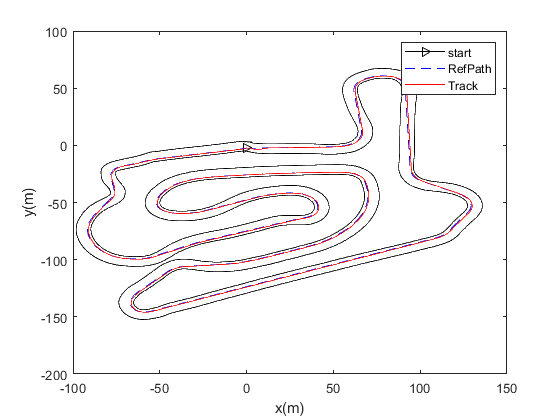

plot_num= 1:s_run;
close;

figure();
plot(xy_ref(1,1), xy_ref(1,2), "Color", 'black', 'linewidth', 0.5, "LineStyle","-", "Marker",">");
hold on;
plot(xy_ref(plot_num, 1), xy_ref(plot_num, 2), 'linewidth', 0.5, "Color", 'blue', "LineStyle","--");
hold on;
plot(states_hist(:,1), states_hist(:,2), 'linewidth', 0.5, "Color", 'red');
hold on;
plot(bound_outer_table.x_Outer_x, bound_outer_table.outer_y, 'black', 'LineWidth', 0.7)
hold on;
plot(bound_inner_table.x_Inner_x, bound_inner_table.inner_y, 'black','LineWidth', 0.7)
hold off
legend('start', 'RefPath', 'Track');
xlabel("x(m)")
ylabel("y(m)")

**plot steer input vs time**

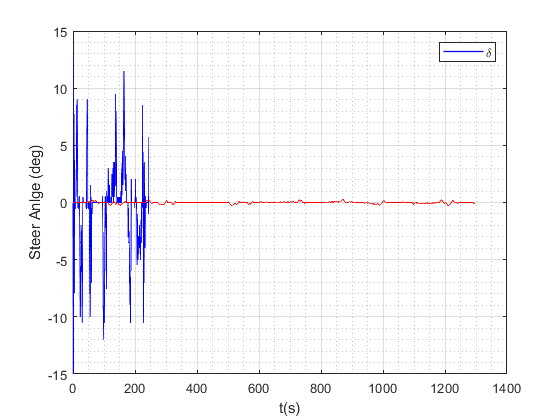

t_num= dt.* [1:1:length(u_hist)];
figure();

plot(t_num, rad2deg(u_hist(:,3)), 'blue', 'LineWidth', 1.0);
% hold on;
% plot(steer_ref, 'red', 'LineWidth', 1.0);
% hold off;
legend('\delta');
grid on; grid minor;
ylabel("Steer Anlge (deg)")
xlabel("t(s)")

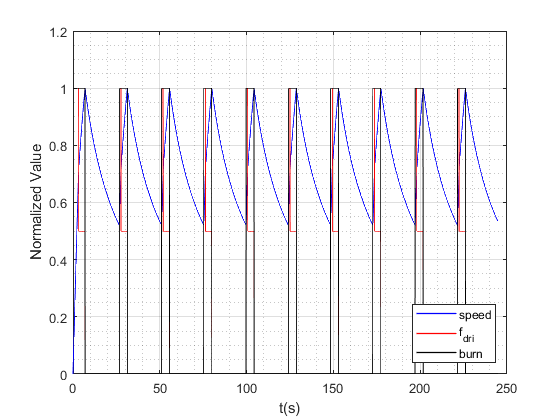



figure();
plot(t_num ,states_hist(:,4)/(25/3.6), 'linewidth', 1.0, "Color", 'blue');
hold on;
plot(t_num , u_hist(:,1), 'linewidth', 1.0, "Color", 'red');
hold on;
plot(t_num ,u_hist(:,2), 'linewidth', 1.0, "Color", 'black');
hold off;
legend('speed', 'f_{dri}', 'burn', "Location", "southeast");
grid on; grid minor;
xlabel("t(s)")
ylabel("Normalized Value")

**plot steer input vs distance**

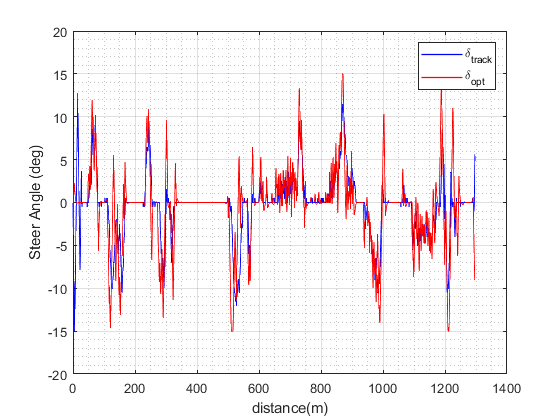

dist_num= 0: s_run/length(u_hist):s_run;

figure();
plot(dist_num(1:end-1), rad2deg(u_hist(:,3)), 'blue', 'LineWidth', 1.0);
hold on;
plot(rad2deg(steer_ref), 'red', 'LineWidth', 1.0);
hold off;
legend('\delta_{track}', '\delta_{opt}');
grid on; grid minor;
xlabel('distance(m)')
ylabel('Steer Angle (deg)')

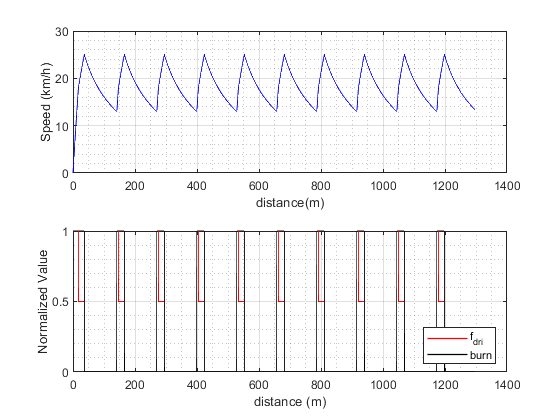


figure();
subplot(2,1,1)
plot(dist_num(1:end-1) ,states_hist(:,4)*3.6, 'linewidth', 1.0, "Color", 'blue');
xlabel("distance(m)")
ylabel("Speed (km/h)")
grid on; grid minor;

subplot(2,1,2)
plot(dist_num(1:end-1) , u_hist(:,1), 'linewidth', 1.0, "Color", 'red');
hold on;
plot(dist_num(1:end-1) ,u_hist(:,2), 'linewidth', 1.0, "Color", 'black');
hold off;
legend('f_{dri}', 'burn', "Location", "southeast");
grid on; grid minor;
xlabel("distance (m)")
ylabel("Normalized Value")